# TCLab Radiative Heat Transfer

### **Objective: **Simulate an energy balance model with radiative and convective heat transfer

The temperature of the transistor increases as electrical current flows through the small device. Energy is dispersed away from the transistor with two primary mechanisms: convection and radiation. The amount of heat lost by convection ($q_{conv}$) is proportional to the temperature difference between the transistor ($T$) and the surrounding air temperature ($T_a$).


$$m \ c_p \frac{dT}{dt}=UA(T_a-T)+\epsilon \sigma A(T_\infty^4-T^4)+\alpha Q$$


The amount of heat lost by radiative heat transfer ($q_{rad}$) is proportional to the 4th power of the temperature between the transistor temperature ($T^4$) and the surrounding objects ($T_\infty^4$).

### Background on Convective and Radiative Heat Transfer

There are several modes of heat transfer including *radiative*, *convective*, and *conductive*. *Radiative heat transfer* is from the motion of particles and emitted as electromagnetic photons primarily as infrared radiation. *Convective heat transfer* is with the surrounding fluid such as air. Convection can be forced such as from a blower or natural such as in quiescent conditions. *Conductive heat transfer* is through solid contact as the energy transfers away but, unlike convection, the contact material is stationary.

#### A) Heat Transfer Modes

For each situation, determine weather Radiation, Conduction, and Convection or a combination of these best describe the heat transfer situation. The solutions to these sections will be at the bottom of the document.

- Hair is dried with a blow dryer.

- A pan is heated on a gas stove.

- Food is cooked in the hot pan.

- Sunlight warms the ground

#### B) Heat Transfer with Increased Temperature

As temperature increases from a low temperature ($-20^\circ \text{C}$) to a relatively high temperature ($80^\circ \text{C}$) which heat transfer mode increases relatively more as the temperature increases?

- Convection increases relatively more at high temperature

- Radiation increases relatively more at high temperature

- Radiative and convective heat transfer increase relatively the same as the temperature increases

#### C) Factors that Influence Heat Transfer

Equation for convection heat loss:


$$q_{conv}=UA(T_a-T)$$


Equation for radiation heat loss:


$$q_{rad}=\epsilon \sigma A(T_\infty^4-T^4)$$


1. Which of these factors increases *only *thermal radiation?

- Heat capacity ($c_p$)

- Emissivity ($\epsilon$)

- Mass ($m$)

- surface Area ($A$)

2.  Which of these factors increases *both* thermal radiation and convection?

- Heat capacity ($c_p$)

- Emissivity ($\epsilon$)

- Mass ($m$)

- surface Area ($A$)

## Problem Statement

A finned heat sink is attached to the transistor to increase the surface area and increase the heat removal both by convective and radiative heat transfer. A temperature sensor is attached to the transistor to monitor the temperature.

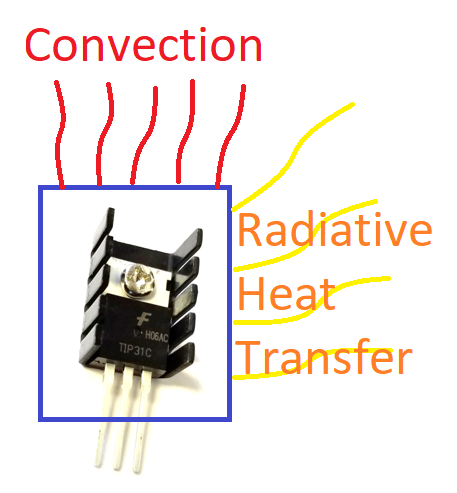

A lumped parameter energy balance model of the Temperature Control Lab (TCLab) assumes that there is one uniform temperature in the control volume and that all heat loss is through radiative and convective heat transfer. The relationship between the heater and the power output is given by $\alpha=0.01 \frac{\text{W}}{\text{\%}}$.


$$m\ c_p \frac{dT}{dt} = UA(T_a-T)+\epsilon \sigma A(T_\infty^4-T^4)+\alpha Q$$


With the temperature initially at ambient temperature (TaTa), simulate the change in temperature over the 5 minutes when heater $Q$ is adjusted to 50%. Use values of $m=0.004\ \text{kg}$, $\epsilon=0.9$, $A=0.0012\ \text{m}^2$, $c_p=500 \frac{\text{J}}{\text{m}^2\text{K}}$, $U=5 \frac{\text{W}}{\text{m}^2\text{K}}$, $\sigma=5.67*10^{-8} \frac{\text{W}}{\text{m}^2\text{K}^4}$, and $T_\infty = T_a=23^\circ \text{C}$. Compare the simulated temperature response to data from the TCLab. **Additionally, show how much heat is lost through convective and radiative heat loss throughout the 5 minute period.** Add a simulation prediction to the script below to compare with the TCLab data.

#### TCLab Steptest

clc; clear all; close all;
tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename)

n = 300;  % number of seconds to test
time = linspace(0, n, n+1);

% Collect data
filename = "L4_TCLab_data.csv";
absolute_path = fullfile(directory, filename)

try % try to read from file first
    A = readmatrix(absolute_path)
    tm = A(:,1);
    T1 = A(:,2);
    display('TCLab Data read from file')
    
catch % if file can not be found, simulate
    try 
        % initialize lab
        lab = tclab;
        
        % loop through
        T1 = zeros(n+1, 1);
        tm = zeros(n+1, 1);
        lab.Q1(50);
        tic;
        for i=1:n+1
            tm(i) = toc;
            T1(i) = lab.T1;
            plot(tm(1:i), T1(1:i), 'r.')
            xlabel('Time (sec)')
            ylabel('Temperature (C)')
            pause(1-min(1,toc-tm(i)));
        end
        lab.off;
        clear lab;
        
        % save
        A = [tm T1]
        writematrix(A, absolute_path, 'Delimiter', ',')
        
    catch % if an error, turn off heater and close
        lab.off;
        clear lab;
    end
    
end

USE `ode45` AND THE LUMPED PARAMETER ENERGY BALANCE ABOVE TO SIMULATE THE TCLab TEMPERATURE

viewSolution1(false)


PLOT MEASURED TEMPERATURE AND SIMULATED TEMPERATURE OVER TIME

viewSolution2(false)

subplot(2,1,1)
plot(tm, T1)
hold on;

PLOT CONTRIBUTIONS OF CONVECTION AND RADIATION

ADD LUMPED PARAMETER FUNCTION BELOW FOR SIMULATION

### Solutions

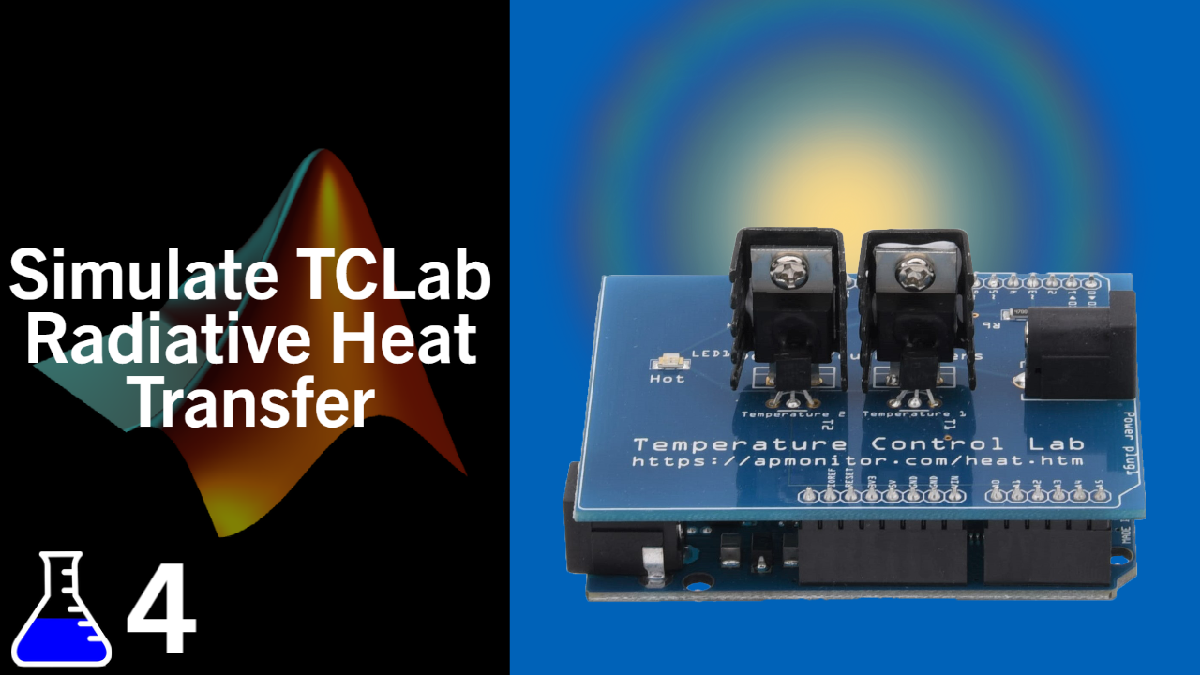

#### [View solution video](https://youtu.be/oE62RWN4oJM)

function viewSolution1(view)
if view
    disp("%%%% Integrate derivative function"+ newline + ...
        "[t,Tsim] = ode45(@(t,T) labSim(t,T, time, 23); %" + newline + ...
        "U = 5.0;"+ newline + ...
        "A = 0.0012;"+ newline + ...
        "alpha = 0.01;"+ newline + ...
        "eps = .9;"+ newline + ...
        "sigma = 5.67e-8;"+ newline + ...
        "Ta = 23;"+ newline + ...
        "Cp = 500;"+ newline + ...
        "m = .004;"+ newline + ...
        "TaK = Ta +273.15;"+ newline + ...
        "convection = U*A*(Ta-Tsim);"+ newline + ...
        "radiation = sigma(eps*A*(Tak.^4-(Tsim+273.15).^4);"+ newline + ...
        "loss = convection + radiation;"+ newline + ...
        "gain = alpha*50;"+ newline + newline + newline+ ...
        "%%% ADD LUMPED PARAMETER FUNCTION BELOW FOR SIMULATION"+ newline + ...
        "function dTdt = labSim(~,T)"+ newline + ...
        "U = 5.0;"+ newline + ...
        "A = 0.0012;"+ newline + ...
        "alpha = 0.01;"+ newline + ...
        "eps = .9;"+ newline + ...
        "sigma = 5.67e-8;"+ newline + ...
        "Ta = 23;"+ newline + ...
        "Cp = 500;"+ newline + ...
        "m = .004;"+ newline + ...
        "TaK = Ta +273.15;"+ newline + ...
        "%%%% Derivative term combined"+ newline + ...
        "dTdt = (U*A*(Ta-T) + sigma*eps*A*(TaK^4-TK^4) + alpha*50)/(m*Cp);"+ newline + ...
        "end")
end
end


function viewSolution2(view)
if view
    disp("%%% PLOT MEASURED TEMPERATURE AND SIMULATED TEMPERATURE OVER TIME"+ newline + ...
        "subplot(2,1,1)"+ newline + ...
        "plot(tm, T1)"+ newline + ...
        "hold on;"+ newline + ...
        "plot(time, Tsim)"+ newline + ...
        "hold off;"+ newline + newline + newline+...
        "%%%% PLOT CONTRIBUTIONS OF CONVECTION AND RADIATION"+ newline + ...
        "subplot(2,1,2)"+ newline + ...
        "plot(time, convection)"+ newline + ...
        "hold on;"+ newline + ...
        "plot(time, radiation)"+ newline + ...
        "plot(time, loss)"+ newline + ...
        "plot(time, gain)"+ newline + ...
        "legend('Convection', 'Radiation', 'loss', 'Gain')"+ newline + ...
        "xlabel('Time (sec)')"+ newline + ...
        "ylabel('Energy')")
end
end
